# Planification optimale de centrales de production électrique

#### Réalisé par  ` KENGNE Fresnel `  et    `SIBEFEU Emmanuel`

# Première partie

## Descriptif du problème

Vous devez planifier la production d'un parc de centrales électriques de manière à satisfaire un besoin prévisionnel sur une échelle de temps donnée. Comme l'électricité se stocke mal, il est nécessaire de produire "à la demande". Les contraintes techniques des centrales électriques (ou générateurs électriques) ne permettent pas de répondre instantanément et dans n'importe quelles conditions à cette demande. Il faut donc anticiper la production en fonction du besoin prévisionnel. 

Vous êtes en charge de quatre centrales électriques avec des caractéristiques différentes aussi bien au niveau de contraintes techniques qu'au niveau de leur coût d'exploitation. La capacité de production (ou puissance) d'une centrale en fonctionnement, $P$, est bornée entre deux valeurs limites $P^{\min }$ et $P^{\max }$. Comme la demande n'est que prévisionnelle, il existe une incertitude inhérente à toute prévision. C'est la raison pour laquelle une « réserve » de  production doit être disponible sans délai. Cette réserve est définie comme un pourcentage (R%) de la demande prévue pour chaque tracnhe horaire. La reserve est donc une marge potentielle de production  pour subvenir à une augmentation soudaine et imprévue de la demande par rapport aux prévisions. La contribution d'une centrale à la réserve est égale à la différence entre sa production courante et la production maximale que la centrale peut fournir. 

On prendra %R = 10%.

Le coût d'exploitation d'une centrale est assimilé uniquement à un coût de fonctionnement. Le coût de fonctionnement sur une heure d'une unité  est modélisé comme une fonction non linéaire de la puissance produite pendant cette heure : $C^f \left(P\right)=a^0 +a^1 P^{1\ldotp 1} +a^2 P^2$. 

Les données associées à chacune des 4 centrales sont fournies dans le tableau suivant. Seules les 5 premières colonnes sont utiles pour la première partie. $P^{\min }$ et $P^{\max }$sont exprimées en MW.

La production totale d'électricité, c'est à dire la somme des productions de toutes les centrales, doit satisfaire une demande à chaque instant. On ne tiendra pas compte des pertes en ligne, ni de la localisation de la demande ou de la production. L'horizon de temps considéré est ici une période de 8 heures décomposée en tranche de 1 heure. Le tableau suivant fournit la demande pour chaque tranche horaire. La demande est supposée constante sur la durée d'une tranche.  

clear

%%%%%% Définition des Paramètres
%Paramètres
n = 4;  % Nombre de centrales
m = 8;  % Nombre d'heures (tranches)

% Caractéristiques des centrales (Ligne 1: Pmin, Ligne 2: Pmax)
productions = [75, 60, 25, 20;
               300, 250, 80, 60];

% Coefficients de coût (a0, a1, a2)
coef = [684.74, 585.62, 213.00, 252.00;   % coef(1,:)=a0
        16.83, 16.95, 20.74, 23.60;       % coef(2,:)=a1
        0.0021,0.0042,0.0018,0.0034];     % coef(3,:)=a2

% Demande et Réserve
demande = [450,530,600,540,410,280,290,510];
reste = 0.1*demande;

%%%%%% Définition du problème d'optimisation
cout = optimproblem('ObjectiveSense', 'minimize');

%%%%%% Définition des variables de décision 
x = optimvar('x', m, n, LowerBound=0); % Puissances de production

%%%%%% Définition de la fonction objectif
cout.Objective = m*sum(coef(1,:)) + sum(x.^1.1,1)*coef(2,:).' + sum(x.^2,1)*coef(3,:).';

%%%%%% Définition des contraintes
construpper = [];  % contraintes <=
constrlower = [];  % contraintes >=

% Contraintes de production
for i = 1:n
    for j = 1:m
        construpper = [construpper; 
            x(j,i) <= productions(2,i)
        ];
        constrlower = [constrlower; 
            x(j,i) >= productions(1,i)
        ];
    end
end

% Contraintes de demande
for j = 1:m
    constrlower = [constrlower; sum(x(j,:))>= demande(j);];
end

% Contraintes de reste
for j = 1:m
    constrlower = [constrlower;
        sum(productions(2) - x(j,:)) >= reste(j); 
    ];
end

% Affectation des contraintes au problème
cout.Constraints.ineg1 = construpper;
cout.Constraints.ineg2 = constrlower;

% Défintion des options de l'optimiseur
options = optimoptions('fmincon');
options.Algorithm = 'sqp'; 
options.Display = 'iter';


% Initialisation des variables de décision
x0.x = 150 * ones(m,n);

% Lancer le chronomètre
tic;
% Optimisation : solve
[sol,fval,flag,info]=solve(cout,x0,'solver', 'fmincon','Options',options);


Solving problem using fmincon.
 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           1    1.706751e+05     9.000e+01     1.000e+00     0.000e+00     4.387e+01  
    1           3    1.287492e+05     0.000e+00     1.000e+00     3.644e+02     8.564e+01  
    2           5    1.216063e+05     5.684e-14     1.000e+00     9.715e+01     1.528e+01  
    3           7    1.212960e+05     0.000e+00     1.000e+00     2.619e+01     6.247e+00  
    4           9    1.208309e+05     1.137e-13     1.000e+00     5.511e+01     6.054e+00  
    5          11    1.207461e+05     1.137e-13     1.000e+00     1.459e+01     2.867e+00  
    6          13    1.206697e+05     0.000e+00     1.000e+00     1.887e+01     2.867e+00  
    7          15    1.205973e+05     1.137e-13     1.000e+00     2.543e+01     2.867e+00  
    8          17    1.205775e+05     0.000e+00   

temps = toc;

% AFFICHAGE RESULTAT
% valeur fonction objectif
disp(['Valeur de la fonction objective :', num2str(fval)]);

Valeur de la fonction objective :120529.3288



%Informations sur le processus d'obtention de la solution
disp(info);

              iterations: 50
               funcCount: 101
               algorithm: 'sqp'
                 message: 'Local minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative first-order optimality measure, 9.670527e-07,↵is less than options.OptimalityTolerance = 1.000000e-06, and the relative maximum constraint↵violation, 6.315935e-16, is less than options.ConstraintTolerance = 1.000000e-06.'
         constrviolation: 5.6843e-14
                stepsize: 6.0751e-04
            lssteplength: 1
           firstorderopt: 3.4005e-05
            bestfeasible: [1×1 struct]
     objectivederivative: "reverse-AD"
    constraintderivative: "closed-form"
                  solver: 'fmincon'




% Affichage des solutions optimales
disp('Solutions optimales :');

Solutions optimales :


disp(sol.x);

  221.0246  173.8622   35.1132   20.0000
  263.2530  203.2165   43.5305   20.0000
  300.0000  228.5679   51.4321   20.0000
  268.5374  206.8396   44.6230   20.0000
  199.9592  158.9187   31.1221   20.0000
  128.5899  106.4101   25.0000   20.0000
  134.2801  110.7199   25.0000   20.0000
  252.6872  195.9405   41.3723   20.0000




% Temps mis
disp('Temps mis (en s) :');

Temps mis (en s) :


disp(temps);

    0.1527



# Seconde partie

Une approche plus fine de la planification consiste à chercher la solution optimale en considérant la possibilité d'arrêter une centrale sur une ou plusieurs tranches horaires. L'arrêt et la mise en route d'une centrale sont soumises à des contraintes d'inertie ; en effet, l'arrêt d'une centrale ne peut pas se faire immédiatement après son démarrage. Ainsi pour des raisons de fiabilité, la centrale doit rester en fonctionnement au minimum pendant un certain intervalle de temps, noté $t^{\textrm{up}}$. De même, une durée minimale d'arrêt,  $t^{\textrm{down}}$, doit être respectée avant un nouveau démarrage. Dans le premier tableau, les valeurs de $t^{\textrm{up}}$ et $t^{\textrm{down}}$sont exprimées en nombre de tranches horaires.

Un coût de démarrage, $C^{\textrm{dem}}$, est associé à chaque démarrage (ou redémarrage) d'une centrale (cf. tableau).

Seules les unités en fonctionnement sur une tranche horaire donnée peuvent participer à la réserve.

Les données supplémentaires sont fournies dans le tableau. La valeur* s* dans la dernière colonne correspond à l'état initial de chaque centrale : une valeur positive correspond au nombre de tranches horaires pendant lesquelles la centrale était en fonctionnement avant la période considérée ;  une valeur négative correspond au nombre de tranches horaires pendant lesquelles la centrale était à l'arrêt avant la période considérée. 

clear; clc; close all;

%% --- 1. Définition des Paramètres ---
% Paramètres de base
n = 4; % Nombre de centrales
m = 8; % Nombre d'heures (tranches)

% Caractéristiques des centrales (Ligne 1: Pmin, Ligne 2: Pmax)
productions = [75, 60, 25, 20;
               300, 250, 80, 60];

% Coefficients de coût (a0, a1, a2)
coef = [684.74, 585.62, 213.00, 252.00;   % a0
        16.83, 16.95, 20.74, 23.60;       % a1
        0.0021, 0.0042, 0.0018, 0.0034];  % a2

% Demande et Réserve
demande = [450, 530, 600, 540, 410, 280, 290, 510];
reste = 0.1 * demande;

% Contraintes dynamiques
t_up = [5, 5, 4, 1];     % Temps min de fonctionnement
t_down = [4, 3, 2, 1];   % Temps min d'arrêt

% Coût de démarrage
cout_demarrage = [1100, 400, 350, 0.02];

% État initial (>0: heures en marche, <0: heures à l'arrêt)
etat_initial = [8, 8, -5, -5];

%% --- 2. Linéarisation du Coût Variable ---
% Le coût variable est C_f(P) = a1*P^1.1 + a2*P^2.
% On l'approxime par morceaux (Piecewise Linear) pour utiliser intlinprog.

% Choix du nombre de segments
nb_segments = 5; 
pentes = zeros(n, nb_segments);
ordonnees = zeros(n, nb_segments);

for i = 1:n
    % Création des points de discrétisation entre Pmin et Pmax
    P_points = linspace(productions(1,i), productions(2,i), nb_segments + 1);
    
    % Calcul du coût variable exact aux points
    cout_pts = coef(2,i) * P_points.^1.1 + coef(3,i) * P_points.^2;
    
    for k = 1:nb_segments
        % Calcul de la pente (m) et de l'ordonnée à l'origine (b)
        % Equation de la droite : y = m*P + b
        dP = P_points(k+1) - P_points(k);
        dC = cout_pts(k+1) - cout_pts(k);
        pentes(i,k) = dC / dP;
        
        % L'ordonnée est ajustée pour la variable binaire x
        % b = Coût - m*P
        ordonnees(i,k) = cout_pts(k) - pentes(i,k) * P_points(k);
    end
end

%% --- 3. Modélisation (OptimProblem) ---
probleme = optimproblem('ObjectiveSense', 'minimize');

% -- Variables de décision --
P = optimvar('P', m, n, 'LowerBound', 0);           % Puissance
x = optimvar('x', m, n, 'Type', 'integer', 'LowerBound', 0, 'UpperBound', 1); % État (On/Off)
y = optimvar('y', m, n, 'Type', 'integer', 'LowerBound', 0, 'UpperBound', 1); % Démarrage
C_var_approx = optimvar('C_var_approx', m, n, 'LowerBound', 0); % Variable auxiliaire de coût

% -- Fonction Objectif --
% Coût Total = Coûts Fixes (a0*x) + Coûts Variables (approx) + Coûts Démarrage
Cout_Total = sum(sum( x .* repmat(coef(1,:), m, 1) )) + ... 
             sum(sum( C_var_approx )) + ...                 
             sum(sum( y .* repmat(cout_demarrage, m, 1) )); 

probleme.Objective = Cout_Total;

% -- Contraintes --

% 1. Contraintes de linéarisation
for i = 1:n
    for k = 1:nb_segments
        % C_var_approx >= pente*P + ordonnee*x
        nom_constr = sprintf('Lin_C%d_Seg%d', i, k);
        probleme.Constraints.(nom_constr) = ...
            C_var_approx(:,i) >= pentes(i,k) * P(:,i) + ordonnees(i,k) * x(:,i);
    end
end

% 2. Bornes de puissance (liées à l'état x)
for i = 1:n
    probleme.Constraints.(sprintf('Pmax_C%d', i)) = P(:,i) <= productions(2,i) * x(:,i);
    probleme.Constraints.(sprintf('Pmin_C%d', i)) = P(:,i) >= productions(1,i) * x(:,i);
end

% 3. Équilibre Offre-Demande
probleme.Constraints.Equilibre = sum(P, 2) >= demande';

% 4. Réserve (Somme des marges disponibles >= reste)
% Marge = (Pmax - P)*x
reserve_dispo = sum(x .* repmat(productions(2,:), m, 1), 2) - sum(P, 2);
probleme.Constraints.Reserve = reserve_dispo >= reste';

% 5. Logique de Démarrage (y >= x(t) - x(t-1))
for i = 1:n
    % Gestion état initial
    x_prec = (etat_initial(i) > 0); % 1 si en marche avant, 0 sinon
    
    probleme.Constraints.(sprintf('Demarrage_T1_C%d', i)) = y(1,i) >= x(1,i) - x_prec;
    probleme.Constraints.(sprintf('Demarrage_C%d', i)) = y(2:end,i) >= x(2:end,i) - x(1:end-1,i);
end

% 6. Temps minimum de fonctionnement (t_up)
for i = 1:n
    Duree = t_up(i);
    for j = 1:m
        idx_fin = min(m, j + Duree - 1);
        len_fenetre = idx_fin - j + 1;
        probleme.Constraints.(sprintf('MinUp_C%d_H%d', i, j)) = ...
            sum(x(j:idx_fin, i)) >= len_fenetre * y(j,i);
    end
end

% 7. Temps minimum d'arrêt (t_down)
for i = 1:n
    Duree = t_down(i);
    % Cas j=1
    x_prec = (etat_initial(i) > 0);
    idx_fin = min(m, Duree); 
    probleme.Constraints.(sprintf('MinDown_T1_C%d', i)) = ...
        sum(1 - x(1:idx_fin, i)) >= idx_fin * (x_prec - x(1,i));
        
    % Cas j=2 à 8
    for j = 2:m
        idx_fin = min(m, j + Duree - 1);
        len_fenetre = idx_fin - j + 1;
        probleme.Constraints.(sprintf('MinDown_C%d_H%d', i, j)) = ...
            sum(1 - x(j:idx_fin, i)) >= len_fenetre * (x(j-1,i) - x(j,i));
    end
end

%% --- 4. Résolution ---
% Lancer le chronomètre
tic;

options = optimoptions('intlinprog', 'Display', 'final', 'RelativeGapTolerance', 1e-4);
[sol, fval, exitflag, output] = solve(probleme, 'Options', options);


Solving problem using intlinprog.

Optimal solution found.

Intlinprog stopped at the root node because the objective value is within a gap tolerance of the optimal value, options.AbsoluteGapTolerance = 1e-06. The intcon variables are integer within tolerance, options.ConstraintTolerance = 1e-06.




temps = toc;
%% --- 5. Résultats ---
disp(['Valeur optimale de la fonction objectif : ', num2str(fval)]);

Valeur optimale de la fonction objectif : 118976.2467


disp(['Message du solveur : ', output.message]);

Message du solveur : Optimal solution found.

Intlinprog stopped at the root node because the objective value is within a gap tolerance of the optimal value, options.AbsoluteGapTolerance = 1e-06. The intcon variables are integer within tolerance, options.ConstraintTolerance = 1e-06.



% Affichage du planning
disp('Planning de production (MW) :');

Planning de production (MW) :


disp(array2table(sol.P, 'VariableNames', {'C1', 'C2', 'C3', 'C4'}, 'RowNames', {'H1','H2','H3','H4','H5','H6','H7','H8'}));

          C1     C2         C3            C4     
          ___    ___    __________    ___________

    H1    240    174            36              0
    H2    271    212            47              0
    H3    300    233            47             20
    H4    281    212            47    -7.1054e-15
    H5    236    174             0              0
    H6    165    115             0              0
    H7    165    125             0              0
    H8    278    212    5.6843e-14             20




disp('État des centrales (1=ON, 0=OFF) :');

État des centrales (1=ON, 0=OFF) :


disp(array2table(sol.x, 'VariableNames', {'C1', 'C2', 'C3', 'C4'}, 'RowNames', {'H1','H2','H3','H4','H5','H6','H7','H8'}));

          C1    C2    C3    C4
          __    __    __    __

    H1    1     1     1     0 
    H2    1     1     1     0 
    H3    1     1     1     1 
    H4    1     1     1     0 
    H5    1     1     0     0 
    H6    1     1     0     0 
    H7    1     1     0     0 
    H8    1     1     0     1 




disp('Démarrages (1=Start) :');

Démarrages (1=Start) :


disp(array2table(sol.y, 'VariableNames', {'C1', 'C2', 'C3', 'C4'}, 'RowNames', {'H1','H2','H3','H4','H5','H6','H7','H8'}));

          C1    C2    C3    C4
          __    __    __    __

    H1    0     0     1     0 
    H2    0     0     0     0 
    H3    0     0     0     1 
    H4    0     0     0     0 
    H5    0     0     0     0 
    H6    0     0     0     0 
    H7    0     0     0     0 
    H8    0     0     0     1 





%% --- 5. Analyse de la solution et de la performance ---

% A. ANALYSE DES VALEURS OPTIMALES (Physique & Économique)
disp('================================================');

disp('   ANALYSE DETAILLEE DES RESULTATS');

   ANALYSE DETAILLEE DES RESULTATS


disp('================================================');


% 1. Décomposition des coûts
% Calcul basé sur les variables de la solution optimale
cout_fixe_total = sum(sum(sol.x .* repmat(coef(1,:), m, 1)));
cout_variable_total = sum(sum(sol.C_var_approx));
cout_demarrage_total = sum(sum(sol.y .* repmat(cout_demarrage, m, 1)));

fprintf('Coût Total          : %.2f\n', fval);

Coût Total          : 118976.25


fprintf('  - Coûts Fixes     : %.2f (%.1f%%)\n', cout_fixe_total, (cout_fixe_total/fval)*100);

  - Coûts Fixes     : 11518.88 (9.7%)


fprintf('  - Coûts Variables : %.2f (%.1f%%)\n', cout_variable_total, (cout_variable_total/fval)*100);

  - Coûts Variables : 107107.33 (90.0%)


fprintf('  - Coûts Démarrage : %.2f (%.1f%%)\n', cout_demarrage_total, (cout_demarrage_total/fval)*100);

  - Coûts Démarrage : 350.04 (0.3%)



% 2. Vérification de la réserve
% productions(2,:) correspond à Pmax
reserve_effective = sum(sol.x .* repmat(productions(2,:), m, 1), 2) - sum(sol.P, 2);
reserve_requise = 0.1 * demande';
marge_reserve = reserve_effective - reserve_requise;
min_marge = min(marge_reserve);

fprintf('\nÉtat de la réserve :\n');


État de la réserve :


if min_marge >= -1e-4 % Tolérance numérique
    fprintf('Contrainte de réserve respectée sur toutes les tranches.\n');
else
    fprintf('Violation de réserve détectée.\n');
end

Contrainte de réserve respectée sur toutes les tranches.



% B. ANALYSE DE L''ALGORITHME (Performance)
disp(' ');

disp('================================================');

disp('   PERFORMANCE DE L''ALGORITHME (MILP)');

   PERFORMANCE DE L'ALGORITHME (MILP)


disp('================================================');


% 1. Convergence
fprintf('Statut de sortie (ExitFlag) : %d\n', exitflag);

Statut de sortie (ExitFlag) : 1


if exitflag == 1
    disp('L''algorithme a convergé vers une solution optimale.');
elseif exitflag == 0
    disp('Limite de temps ou d''itérations atteinte (solution sous-optimale potentielle).');
else
    disp('Problème de convergence (infaisable ou erreur).');
end

L'algorithme a convergé vers une solution optimale.



% 2. Analyse de l'Unicité et Précision (Gap)
if isfield(output, 'relativegap')
    gap = output.relativegap;
else
    gap = 0;
end
fprintf('Gap Relatif (MIP Gap)       : %.4e\n', gap);

Gap Relatif (MIP Gap)       : 0.0000e+00


disp('Analyse Unicité : Le solveur garantit d''avoir trouvé le minimum global (aux tolérances près). Cependant, en programmation entière, il peut exister plusieurs combinaisons donnant exactement le même coût, mais la valeur objective est unique.');

Analyse Unicité : Le solveur garantit d'avoir trouvé le minimum global (aux tolérances près). Cependant, en programmation entière, il peut exister plusieurs combinaisons donnant exactement le même coût, mais la valeur objective est unique.



% 3. Complexité calculatoire
if isfield(output, 'iterations')
    fprintf('Nombre d''itérations : %d\n', output.iterations);
else
    fprintf('Nombre d''itérations non disponible (info non fournie par ce solveur)\n');
end

Nombre d'itérations non disponible (info non fournie par ce solveur)



if isfield(output, 'numNode')
    fprintf('Nombre de noeuds explorés   : %d\n', output.numNode);
end

% Note sur le temps
fprintf('Temps mis (en s) : %.4f s\n', temps);

Temps mis (en s) : 0.0498 s


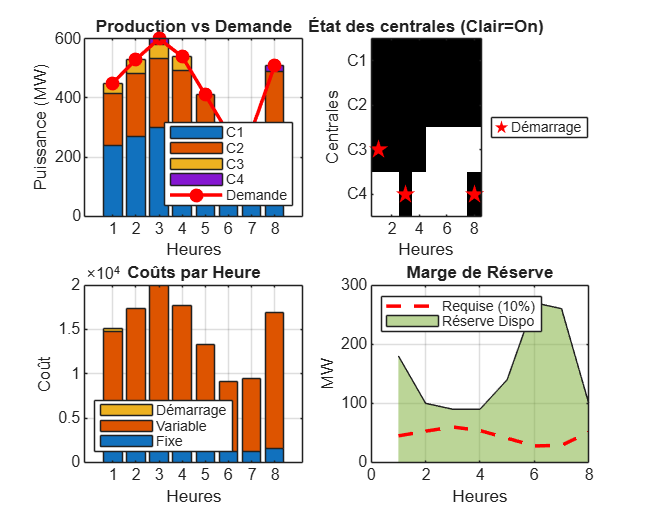


%% --- 6. Visualisation Graphique ---
figure('Name', 'Planification Optimale', 'Color', 'w', 'Position', [100, 100, 1000, 800]);

% Graphique 1 : Empilement de la production vs Demande
subplot(2, 2, 1);
bar(1:m, sol.P, 'stacked', 'FaceColor', 'flat');
% Couleurs personnalisées
couleurs = [0 0.4470 0.7410; 0.8500 0.3250 0.0980; 0.9290 0.6940 0.1250; 0.4940 0.1840 0.5560];
colormap(gca, couleurs);
hold on;
plot(1:m, demande, 'r-o', 'LineWidth', 2, 'MarkerFaceColor', 'r');
title('Production vs Demande');
xlabel('Heures'); ylabel('Puissance (MW)');
legend({'C1', 'C2', 'C3', 'C4', 'Demande'}, 'Location', 'southeast');
grid on;

% Graphique 2 : État des centrales
subplot(2, 2, 2);
imagesc(sol.x'); 
colormap(gca, flipud(gray)); % Blanc=1 (Marche), Gris=0 (Arrêt)
title('État des centrales (Clair=On)');
xlabel('Heures'); ylabel('Centrales');
set(gca, 'YTick', 1:n, 'YTickLabel', {'C1', 'C2', 'C3', 'C4'});
% Démarrages en rouge
[row_start, col_start] = find(sol.y' > 0.9);
hold on;
plot(col_start, row_start, 'rp', 'MarkerSize', 10, 'MarkerFaceColor', 'r');
legend('Démarrage', 'Location', 'eastoutside');

% Graphique 3 : Structure des coûts
subplot(2, 2, 3);
cout_fixe_h = sum(sol.x .* repmat(coef(1,:), m, 1), 2);
cout_var_h = sum(sol.C_var_approx, 2);
cout_dem_h = sum(sol.y .* repmat(cout_demarrage, m, 1), 2);
bar(1:m, [cout_fixe_h, cout_var_h, cout_dem_h], 'stacked');
title('Coûts par Heure');
xlabel('Heures'); ylabel('Coût');
legend({'Fixe', 'Variable', 'Démarrage'}, 'Location', 'southwest');
grid on;

% Graphique 4 : Marge de Réserve
subplot(2, 2, 4);
area(1:m, reserve_effective, 'FaceColor', [0.4660 0.6740 0.1880], 'FaceAlpha', 0.5);
hold on;
plot(1:m, reste, 'r--', 'LineWidth', 2);
title('Marge de Réserve');
xlabel('Heures'); ylabel('MW');
legend({'Réserve Dispo', 'Requise (10%)'}, 'Location', 'northwest');
grid on;